clear; close; clc;
%flight condtion for cruise
load('CARTRIDGE_105_MILLIMETER_HERA_M927.mat')

%d = CARTRIDGE_105_MILLIMETER_HERA_M927.Hydrolic_Diameter;
%l = CARTRIDGE_105_MILLIMETER_HERA_M927.Projectile_Length;
       

%S_ref = pi*d/4;
%Weight_50 = (CARTRIDGE_105_MILLIMETER_HERA_M927.Projectile_Mass - CARTRIDGE_105_MILLIMETER_HERA_M927.Propellant_Mass/2) * 9.81; % wieght at 50% fuel load
%Lift = Weight_50;

isCoasting = true; % we are doing both true and false (this should not be defined here)

%height = 1000; % we will do this for various altitudes. not yet implemented
height = 0; % we will do this for various altitudes. not yet implemented


% dimentions that match fleeman graph
% for debugging
S_ref = convlength(convlength(2,"ft","m"),"ft","m") % convert ft^2 to m^2

S_ref = 0.1858

d = 4 * S_ref / pi;
d_noseTip = 0; % assumption
d_bt = d; % assumption
l = 10 * d;
l_N = l * 3/10; % assumption
A_nE = 0; % assumption
Weight_50 = convforce(2000,"lbf","N");
Lift = Weight_50;



% initialize looop solution arrays
nPoints = 1000 % 1000 is a good number

nPoints = 1000


%q_bars = logspace(2,4,nPoints) * 47.880259; % logspace in lb/ft^2 to Pa
q_bars = linspace(10^2,10^4,nPoints) * 47.880259; % linspace in lb/ft^2 to Pa

alpha_optimum = zeros(nPoints,0);
V_list = zeros(nPoints,0);


L_over_D_1g = zeros(nPoints,0);
L_over_D_1g_powered = zeros(nPoints,0);

syms alpha

for j = 1:nPoints
    q = q_bars(j);

    [~,a,~,rho] = atmosisa(height);
    V = sqrt(2*q/rho);
    V_list(j) = V;
    M = V/a;
    
    C_L = Lift/(S_ref*q);

    %VPA solve for alpha (produces same results as using Newton-Raphson)
    assume(alpha > 0);
    assumeAlso(alpha < deg2rad(15));

    % there are probably at least two possible alphas for all (but one) C_N
    %double(vpasolve(normalForceCoeff_liftingBody(l,d/2,d/2,0,alpha) == C_L,alpha, .0001)); % this will gereate worse results
    alpha_optimum(j) = double(vpasolve(normalForceCoeff_liftingBody(l,d/2,d/2,0,alpha) == C_L,alpha, deg2rad(15)));

    L_over_D_1g(j) = lift_to_drag_ratio_body(normalForceCoeff_liftingBody(l,d/2,d/2,0,alpha_optimum(j)), ...
        dragCoeff_zeroLift_body(M, q, l, l_N, d, d_noseTip, d_bt, A_nE, true), ...
        alpha_optimum(j));

    % only impact of thrust is here (there seems to be no impact on L/D)
    L_over_D_1g_powered(j) = lift_to_drag_ratio_body(normalForceCoeff_liftingBody(l,d/2,d/2,0,alpha_optimum(j)), dragCoeff_zeroLift_body(M, q, l, l_N, d, d_noseTip, d_bt, A_nE, false), alpha_optimum(j));
end

%cruise_results = {alpha_optimum, L_over_D_1g, L_over_D_1g_powered, q_bars} % as cell array
cruise_result.alpha_optimum = alpha_optimum;
cruise_result.alpha_optimum = q_bars;
cruise_result.L_over_D_1g = L_over_D_1g;
cruise_result.L_over_D_1g_powered = L_over_D_1g_powered;
cruise_result.alt = height;
%cruise_results = {cruise_result} % something like this to madd my results
%to the cell array

alpha_optimum

alpha_optimum =     1.1153    1.0260    0.9547    0.8957    0.8456    0.8024    0.7646    0.7312    0.7014    0.6746    0.6503    0.6282    0.6080    0.5894    0.5722    0.5563    0.5415    0.5277    0.5147    0.5026    0.4911    0.4804    0.4702    0.4605    0.4514    0.4427    0.4344    0.4265    0.4190    0.4118    0.4049    0.3983    0.3920    0.3859    0.3801    0.3745    0.3690    0.3638    0.3588    0.3539    0.3492    0.3447    0.3403    0.3360    0.3319    0.3279    0.3240    0.3203    0.3166    0.3130


L_over_D_1g

L_over_D_1g =     0.4684    0.5798    0.6764    0.7626    0.8409    0.9128    0.9800    1.0436    1.1034    1.1598    1.2133    1.2641    1.3123    1.3583    1.4021    1.4438    1.4837    1.5217    1.5581    1.5928    1.6260    1.6576    1.6879    1.7168    1.7443    1.7706    1.7956    1.8194    1.8421    1.8637    1.8842    1.9037    1.9221    1.9396    1.9560    1.9716    1.9863    2.0001    2.0130    2.0251    2.0364    2.0469    2.0567    2.0658    2.0741    2.0817    2.0887    2.0950    2.1006    2.1057


L_over_D_1g_powered

L_over_D_1g_powered =     0.4684    0.5798    0.6764    0.7626    0.8409    0.9128    0.9800    1.0436    1.1034    1.1598    1.2133    1.2641    1.3123    1.3583    1.4021    1.4438    1.4837    1.5217    1.5581    1.5928    1.6260    1.6576    1.6879    1.7168    1.7443    1.7706    1.7956    1.8194    1.8421    1.8637    1.8842    1.9037    1.9221    1.9396    1.9560    1.9716    1.9863    2.0001    2.0130    2.0251    2.0364    2.0469    2.0567    2.0658    2.0741    2.0817    2.0887    2.0950    2.1006    2.1057


q_bars

q_bars = 1.0e+05 *

    0.0479    0.0526    0.0574    0.0621    0.0669    0.0716    0.0763    0.0811    0.0858    0.0906    0.0953    0.1001    0.1048    0.1096    0.1143    0.1191    0.1238    0.1285    0.1333    0.1380    0.1428    0.1475    0.1523    0.1570    0.1618    0.1665    0.1712    0.1760    0.1807    0.1855    0.1902    0.1950    0.1997    0.2045    0.2092    0.2140    0.2187    0.2234    0.2282    0.2329    0.2377    0.2424    0.2472    0.2519    0.2567    0.2614    0.2661    0.2709    0.2756    0.2804


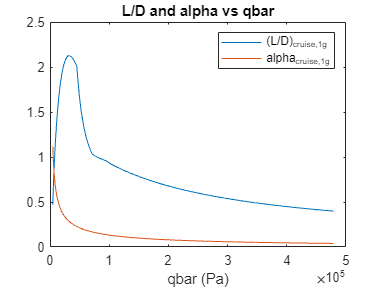


% plot trend of l/d and alpha
plot(q_bars,[L_over_D_1g; alpha_optimum]); title("L/D and alpha vs qbar"); xlabel("qbar (Pa)"); legend(["(L/D)_{cruise,1g}", "alpha_{cruise,1g}"]);

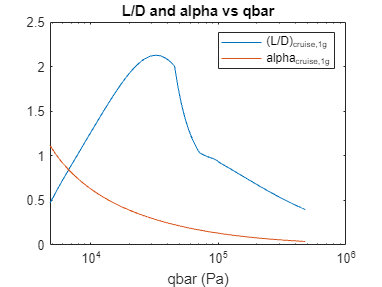

semilogx(q_bars,[L_over_D_1g; alpha_optimum]); title("L/D and alpha vs qbar"); xlabel("qbar (Pa)"); legend(["(L/D)_{cruise,1g}", "alpha_{cruise,1g}"]);

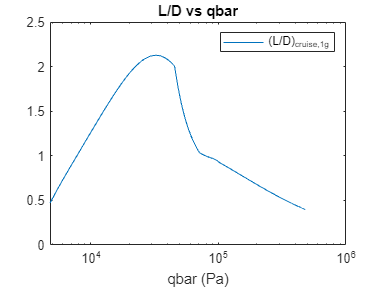


semilogx(q_bars,L_over_D_1g); title("L/D vs qbar"); xlabel("qbar (Pa)"); legend(["(L/D)_{cruise,1g}"]);

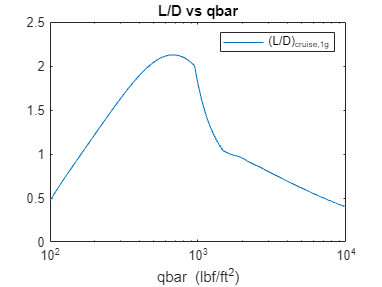

%to match fleeman
semilogx(q_bars/47.880259,L_over_D_1g); title("L/D vs qbar"); xlabel("qbar (lbf/ft^2)"); legend(["(L/D)_{cruise,1g}"]);

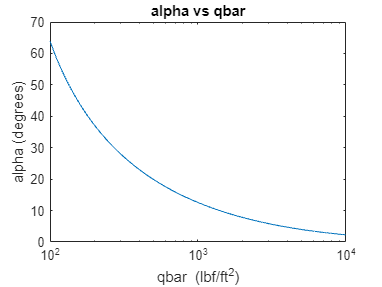


%alpha vs qbar
semilogx(q_bars/47.880259,rad2deg(alpha_optimum)); title("alpha vs qbar"); xlabel("qbar (lbf/ft^2)"); ylabel("alpha (degrees)");

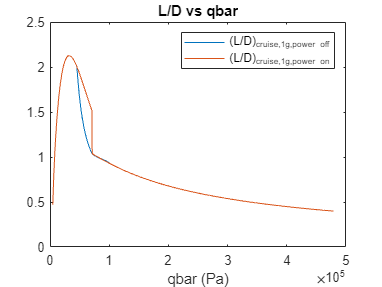


%compare powered and unpowerd
plot(q_bars,[L_over_D_1g; L_over_D_1g_powered]); title("L/D vs qbar"); xlabel("qbar (Pa)"); legend(["(L/D)_{cruise,1g,power off}", "(L/D)_{cruise,1g,power on}"]); % this plot is unintresting as drag reduction is negligeable